# Advanced Application Development: Working with Hierarchical Data

## Advanced app example: Zoo Hierarchy

While MATLAB apps serve a wide variety of needs, a frequent app requirement involves viewing and manipulating a hierarchy data. The Zoo Hierarchy example app (Figure 1) has been designed specifically to provide a simplistic and understandable example for learning how to implement data hierarchy in a modular and programmatically written MATLAB app. This app manages data from a top level, in this case being the entirety of a zoo, down to the lowest level, the individual animals residing there.

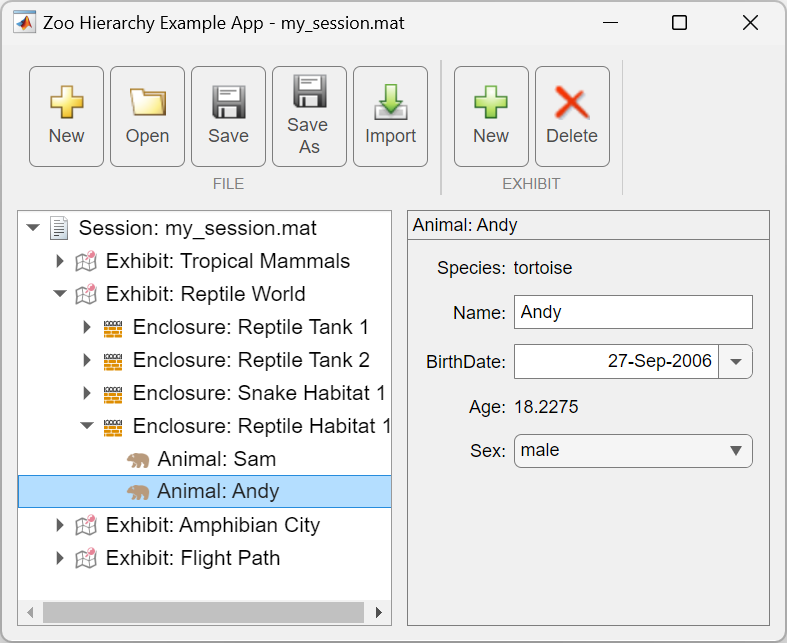

*Figure 1. The zoo hierarchy example app.*

### The Hierarchy

This app enables the user to view and edit data within a tree hierarchy. The tree has multiple different levels described below:

- Session: A single collection of data, also referred to as a "document", in this case corresponding to an entire zoo. A session may contain one or more Exhibit objects inside.

- Exhibit: A subset of a zoo, corresponding to one section or area. An exhibit may have one or more Enclosure objects within it.

- Enclosure: A specific cage enclosure, tank, etc. within an Exhibit. Multiple animals may stay within an enclosure.

- Animal: An individual animal within an Enclosure. This is the lowest level of the hierarchy.

### Class Objects Representing the Data

Each of the items in the hierarchy is implemented using a MATLAB class object. These class objects are linked as a "parent / child" hierarchy. This is shown in Figure 2 below, a Unified Modeling Language (UML) class diagram:

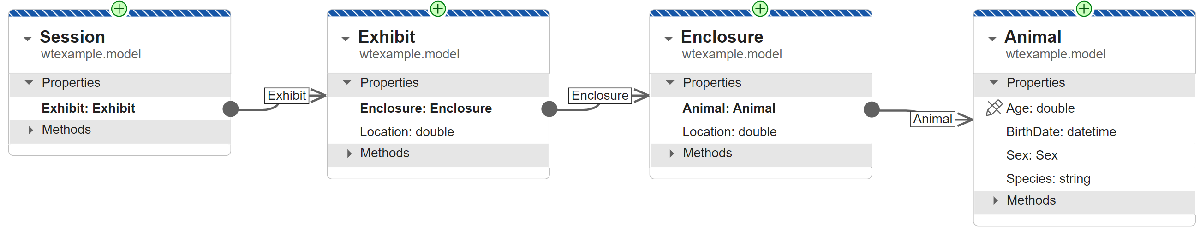

*Figure 2. UML class diagram showing data hierarchy for the zoo session.*

Each of the above class objects provides properties to store the relevant metadata for a given entity.  The first three objects also provide nested hierarchy where a property contains an array of other objects that belong to it, which is known as *composition* from an object-oriented design perspective. 

## Running the Example

Run the example by calling the application's launcher:

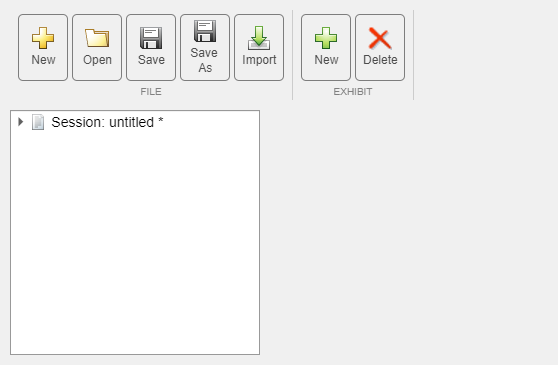

app = WidgetsZooAppLauncher;

Note that this launcher will pre-populate the app with a sample dataset. The optional output argument `app` provides a handle reference to the app. It is an instance of class `wt.example.app.ZooHierarchy`.

## Architecture Considerations

### Why architecture patterns help you work more effectively

Building an app programmatically gives significantly more control over the code structure and architecture. As apps grow in complexity, modular architecture and separation of concerns are important to achieve optimum performance, scalability, and testability. Additionally, following a standard software architecture pattern such as [model-view-controller](https://en.wikipedia.org/wiki/Model%E2%80%93view%E2%80%93controller) (MVC) as shown in Figure 2 enables you to build modular apps from smaller components, rather than having a single monolithic app file.

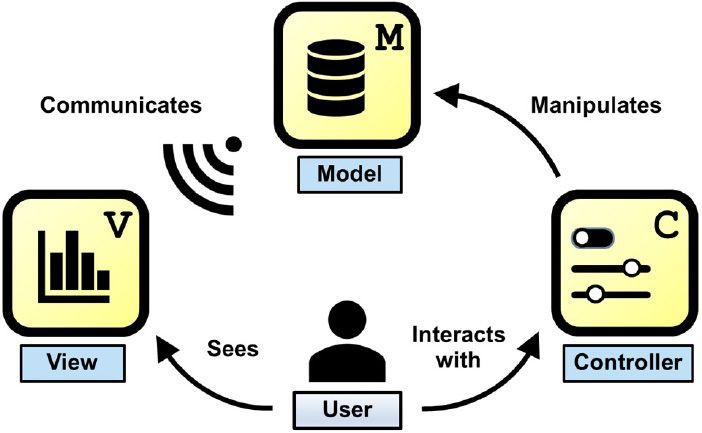

*Figure 3. The model-view-controller (MVC) software architecture pattern.*

For more information about using MVC architecture in MATLAB apps, please see the content below:

- Article: [Developing MATLAB Apps Using the Model-View-Controller Pattern - MATLAB & Simulink](https://www.mathworks.com/company/technical-articles/developing-matlab-apps-using-the-model-view-controller-pattern.html)

- Webinar: [Application Development Strategies in MATLAB - MATLAB](https://www.mathworks.com/videos/application-development-strategies-in-matlab-1689014110815.html)

- Training: [Advanced MATLAB Application Development - MATLAB & Simulink](https://www.mathworks.com/learn/training/advanced-matlab-application-development.html)

### How the backend model was implemented to to manage parameters and data

Class objects were created to represent the *model* for the app, the entity that comprises the app's data, states, and algorithms.  As previously explained and shown in Figure 2, the model is implemented using several class objects:

- [wt.example.model.Session](matlab:open('./+wt\+example\+model\Session.m'))

- [wt.example.model.Exhibit](matlab:open('./+wt\+example\+model\Exhibit.m'))

- [wt.example.model.Enclosure](matlab:open('./+wt\+example\+model\Enclosure.m'))

- [wt.example.model.Animal](matlab:open('./+wt\+example\+model\Animal.m'))

These backend objects were implemented as handle classes to enable accessing the data by reference. This enables the user's session to be in a consistent state, even if portions (such as a single Animal class instance) is being shown within a view/controller class. This is shown in Figure 4:

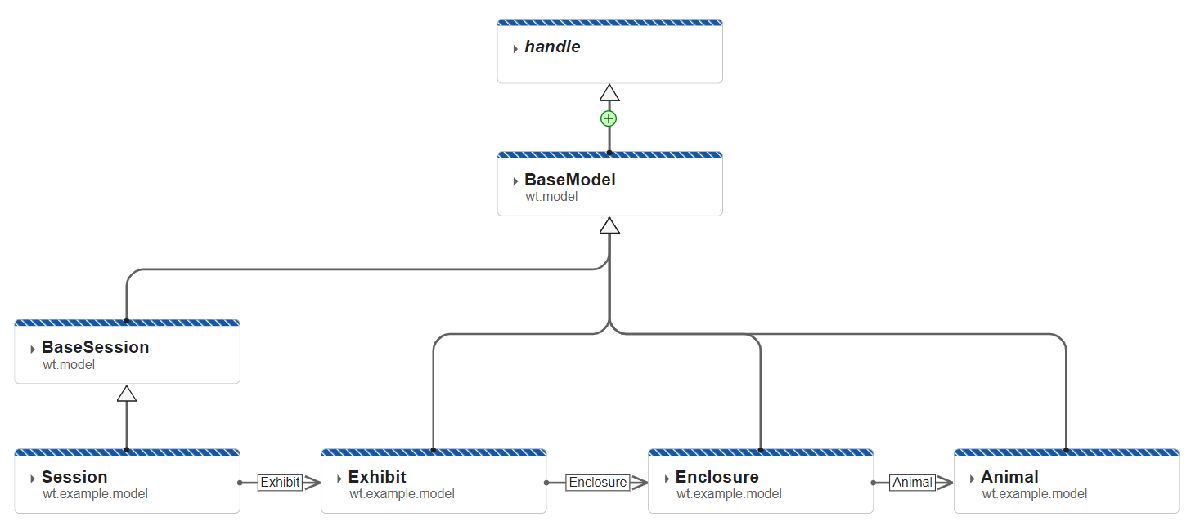

*Figure 4. UML class diagram showing superclass hierarchy, with the four concrete model classes at the bottom*

(Please refer to this article for a discussion of handle vs. value classes: [Developing MATLAB Apps Using the Model-View-Controller Pattern - MATLAB & Simulink](https://www.mathworks.com/company/technical-articles/developing-matlab-apps-using-the-model-view-controller-pattern.html))

For convenience and code modularity reasons, reusable superclasses were developed to provide common functionality of these "model classes". The classes [BaseModel](matlab:open('..\+wt\+model\BaseModel.m')) and [BaseSession](matlab:open('..\+wt\+model\BaseSession.m')) provide the concrete classes (Session, Exhibit, Enclosure, Animal) with change notification from a public `PropertyChanged` event. This provides a simple mechanism for the view/controller classes displaying a model to listen to model changes and be alerted if a display update needs to happen.

### How the frontend implementation utilized a modular MVC pattern

The app has four different types of data to view and edit on the right side, one for each of the four model classes. Each of these model classes has a corresponding view/controller component. (In the case of this app, the view and controller functions are desired to be shown together, so hybrid view/controller classes are implemented for each of the four views. These are shown in Figure 5:

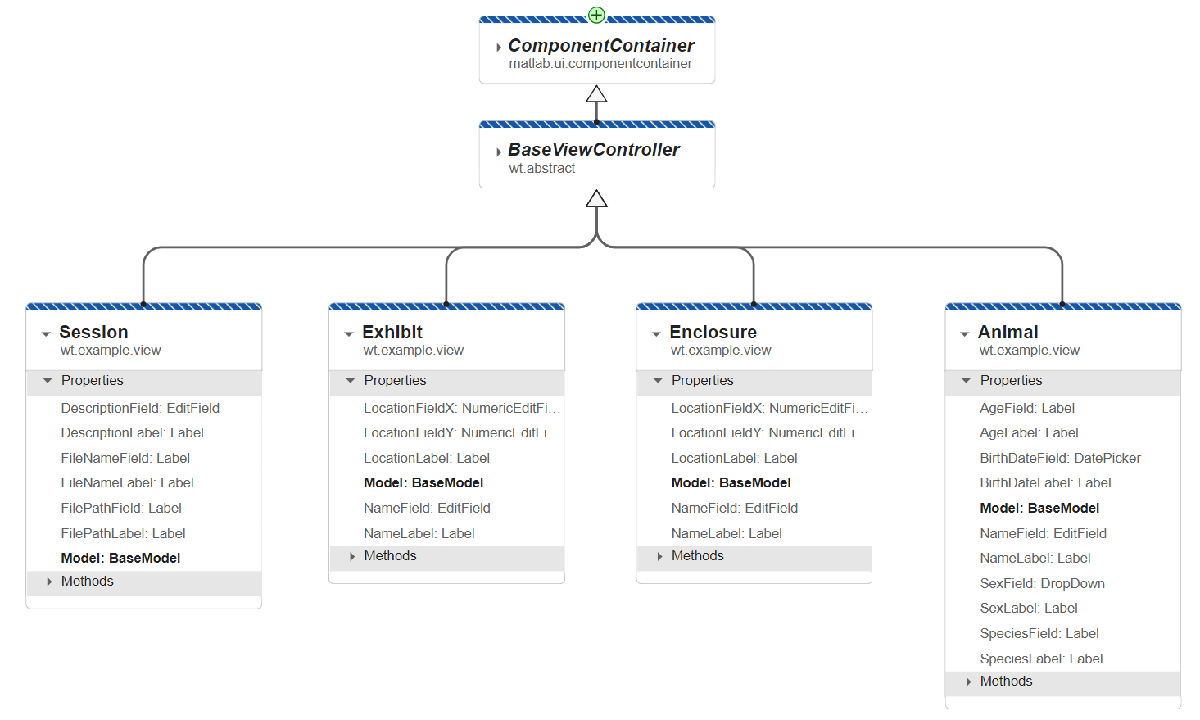

*Figure 5. UML class diagram showing the four view/controller components that display their respective model classes*

#### Example

Aside from use in the app itself, these view/controller components are standalone, reusable modules that may also be instantiated as standalone components:

% Create the model for an animal
animalA = wt.example.model.Animal;
animalA.Species = "Lion";
animalA.Name = "Simba";
animalA.Sex = "male";
animalA.BirthDate = "March 9, 2017";
disp(animalA)

  Animal with properties:

      Species: "Lion"
    BirthDate: 09-Mar-2017
          Sex: male
          Age: 7.7941
         Name: "Simba"



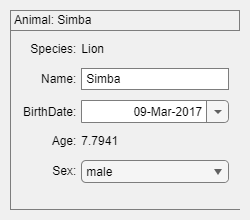


% Create a figure and grid layout
fig1 = uifigure("Position",[100 100 250 220]);
grid1 = uigridlayout(fig1,[1 1]);

% Create a view in the figure's grid, providing a model
view1 = wt.example.view.Animal(grid1, "Model", animalA);

#### Tree hierarchy

#### Context pane switching